# Benchmarking policies

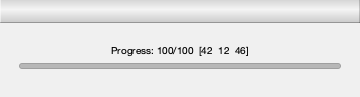

nsims = 100;
winner = repmat(' ',1,nsims);

wt = waitbar(0,'Running...');
for i = 1:nsims
    [~,winner(i)] = play_game([],@policy_rollout,@policy_rollout);
    waitbar(i/nsims,wt,sprintf('Progress: %i/%i  [%i  %i  %i]',i,nsims,sum(winner=='X'),sum(winner=='t'),sum(winner=='O')));
end


[sum(winner=='X') sum(winner=='t') sum(winner=='O')]

ans =     42    12    46
